# Levitador de aire

**Trabajo para el curso sistemas lineales, 2025-1**

**© **[**Universidad EAFIT**](https://www.eafit.edu.co)**, Medellín, Antioquia, Colombia**

- **Santiago López **- [slopezc12@eafit.edu.co](mailto:slopezc12@eafit.edu.co)

- **Ricardo Gandica **- [jrgandicav@eafit.edu.co](mailto:jrgandicav@eafit.edu.co)

## 1. Introducción

El sistema de levitación de aire es un sistema popular en laboratorios de control. El sistema consiste en un tubo vertical con un objeto (bola) moviendose dentro de el. El sistema tiene una entrada de aire, controlada por un ventilador que esta abajo [1]. Toda la deducción de las ecuaciones de estado y del modelo del sistema es de [1]

Para modelar este sistema los autores del articulo consideraron una versión simplificada. La dinámica del sistema de levitación de aire la describe la ecuación (1).

$$m\frac{d^{2}y}{dt^{2}}=\frac{1}{2}\rho AC_{d}(v_{a}-\frac{dy}{dt})^{2}-mg$$ (1)

En esta ecuación, $m$, $\rho$, $A$, $C_d$, $g$  son constantes. $m$ es la masa de la bola, $\rho$ es la densidad de aire en el tubo, $A$ es el área de la bola, $C_d$ es un coeficiente de resistencia y $g$ es la gravedad; $y(t)$ es la variable de salida, la posición vertical de la bola, y $v_a$ es la velocidad de aire en el tubo.

La dinámica del flujo de aire en el tubo se describe con la siguiente ecuación

$\frac{dv_{a}}{dt}=-\frac{1}{\tau_{1}}v_{a}+\frac{K_{f}}{\tau_{1}}u$ (2)

donde $u(t)$ es el poder de entrada que se le envía al ventilador, $\tau_1$ es una constante de tiempo $K_f$ es la ganancia del ventilador.

Estas dos ecuaciones describen el Sistema de Levitador de Aire (ALS) como es descrito en el articulo [1]. Si se reformula el coeficiente de resistencia para considerar la dirección de la bola quedamos con las siguientes ecuaciones.


$$\frac{dx_1}{dt} = x_2$$



$$\frac{dx_2}{dt} = \frac{\alpha}{m} \left(v_a - \frac{dy}{dt}\right) \left|v_a - \frac{dy}{dt}\right| - g$$



$$\frac{dx_3}{dt} = -\frac{1}{\tau_1} x_3 + \frac{K_f}{\tau_1} u.$$


Esto nos deja con las siguientes ecuaciones de estado:


$$\frac{dx_1}{dt} = x_2$$



$$\frac{dx_2}{dt} = \frac{\alpha}{m} \left(x_3 - x_2\right) \left|x_3 - x_2\right| - g$$



$$\frac{dx_3}{dt} = -\frac{1}{\tau_1} x_3 + \frac{K_f}{\tau_1} u.$$


El sistema presentado tiene una simplificación muy grande, y es que el efecto del aire en la altura de la bola no es afectada por la misma altura. Esto significa que no importa que tan alto llegue la bola, el ventilador la va a seguir alzando con la misma fuerza.

Ademas el sistema esta planteado como un ejercicio de control. Por eso, a nuestro sistema le agregamos un controlador. Al agregar un controlador PID, nuestra entrada pasa a ser la altura de referencia en vez del aire de entrada, ya que esto lo controla el controlador.

**Hipótesis 1: Efecto de aumentar la masa de la bola**

- A medida que la masa de la bola aumenta, su inercia también lo hace, lo cual genera una respuesta más lenta al estímulo del ventilador (sube más lentamente).

- Se espera una mayor constante de tiempo, menor sobreimpulso y una posición de equilibrio más baja para la misma entrada.

**Hipótesis 2: Efecto de aumentar la ganancia del ventilador**

- Un mayor $K_f$ implica que el ventilador responde con mayor fuerza ante pequeños cambios en la señal de control.

- Aunque esto permite levantar más fácilmente la bola, también genera mayor sensibilidad y oscilaciones más pronunciadas si el sistema de control no compensa adecuadamente.

- Como el PID es fijo con los mismos parámetros, el sistema puede volverse más oscilatorio e inestable, especialmente si el controlador no está bien ajustado para esa nueva ganancia.

**Hipótesis 3: Efecto de reducir el coeficiente de fricción.**

- Reducir la constante del coeficiente de resistencia $C_d$ implica una menor fuerza de arrastre sobre la bola. Esto hace que la bola acelere más rápido ante cambios en el aire, lo cual puede llevar a menor amortiguamiento.

- El sistema tardará más en estabilizarse, porque tendrá menos disipación y será más propenso a oscilar**, **ya que hay menos disipación de energía en el sistema.

## 2. Métodos

### 2.1 Modelo de Simulink

El sistema descrito en la sección anterior se modeló en **Simulink**.

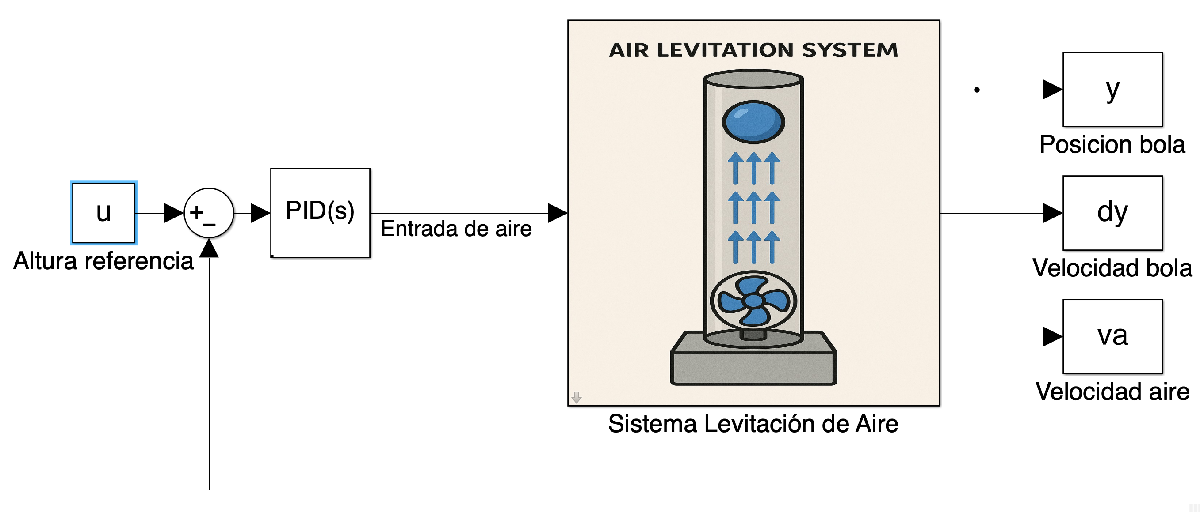

**Figura 1: Modelo de simulink de levitador de aire, con controlador**

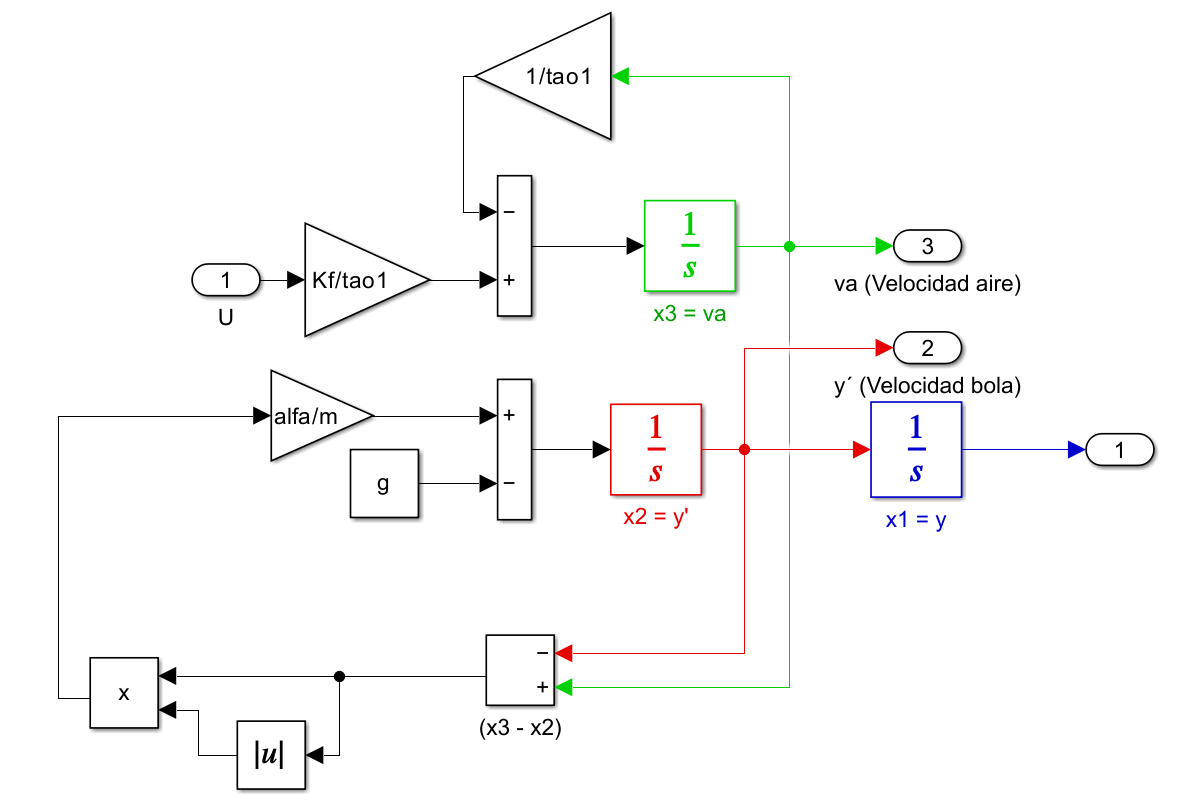

**Figura 2: Subsistema donde se modela el sistema de levitación de aire**

### 2.2 Verificación del modelo

Como el modelo es planteado para usarse en ejercicios de control, nuestro modelo incluye un controlador PID. Para verificar el modelo, calibramos a mano el controlador PID y revisamos que la respuesta del sistema sea similar a la de el articulo [2]. Como usamos un controlador PID, la entrada del sistema cambia de ser el aire del ventilador, a ser el nivel de referencia deseado. De nuestra calibración a mano quedamos con los siguientes parámetros del controlador PID:

$K_P =0.5$, $K_I = 0.1$, $K_D = 0.01$.

De [2] tenemos los siguientes valores para los parámetros:

**Tabla 1: Parametros**

### 2.3 Cambio de entradas

Para los primeros experimentos, se simula el sistema utilizando cinco tipos distintos de entradas: una señal constante, dos señales escalonadas (de distinta magnitud), una señal sinusoidal y una entrada tipo pulso. El propósito de estas pruebas es observar cómo responde el sistema ante diferentes formas de excitación y evaluar su capacidad para alcanzar y mantener la estabilidad bajo diversas condiciones.

En cada experimento se visualizan tres variables clave del sistema: la **posición de la bola **$y$, su **velocidad **$y'
$ y la **velocidad del aire **$v_a$ generada por el ventilador. Estas se grafican en tres subplots apilados verticalmente para facilitar su interpretación individual. Adicionalmente, se incluye un **diagrama de fase** que relaciona la posición y la velocidad de la bola, permitiendo analizar el comportamiento oscilatorio y la convergencia del sistema hacia el equilibrio.

Para garantizar la coherencia entre pruebas, en todos los casos se utilizan los mismos parámetros físicos y de control definidos en la **Tabla 1**, lo que permite aislar el efecto exclusivo de la forma de la entrada sobre la dinámica del sistema.

### 2.4 Cambio de parametros

Con el objetivo de analizar la sensibilidad del sistema frente a sus parámetros físicos, se realiza una serie de simulaciones en las que se modifican individualmente tres parámetros fundamentales: la **masa de la bola **$m$, el **coeficiente de fricción** $C_d$ y la **ganancia del ventilador** $K_f$. En todos los casos, los demás parámetros permanecen constantes según los valores establecidos en la Tabla 1.

Para estas simulaciones, se utiliza una entrada constante que representa un nivel de referencia fijo correspondiente a una fuerza sostenida de levitación que busca estabilizar la bola a una determinada altura. Se escoge un valor constante de entrada equivalente a **5 unidades de señal de control**, que actúa como referencia.

Con el fin de observar mejor las diferencias en el comportamiento del sistema a distintos órdenes de magnitud, los valores de los parámetros se seleccionaron de manera **logarítmica**. Esto permite captar tanto los efectos más sutiles como los más pronunciados, especialmente cuando el sistema responde de forma no lineal ante pequeños cambios en ciertos rangos de parámetros.

El análisis se enfoca en observar la **respuesta temporal de la posición de la bola**, identificando cómo cambios en cada parámetro afectan el comportamiento del sistema, incluyendo el tiempo de estabilización, el sobreimpulso y la posición de equilibrio alcanzada. Esto permitirá validar o refutar las hipótesis planteadas y comprender el papel dinámico que juega cada parámetro en el desempeño global del sistema.

## 3. Resultados

### 3.1 Verificación para diferentes entradas

#### 3.1.1 Verificación con entrada constante

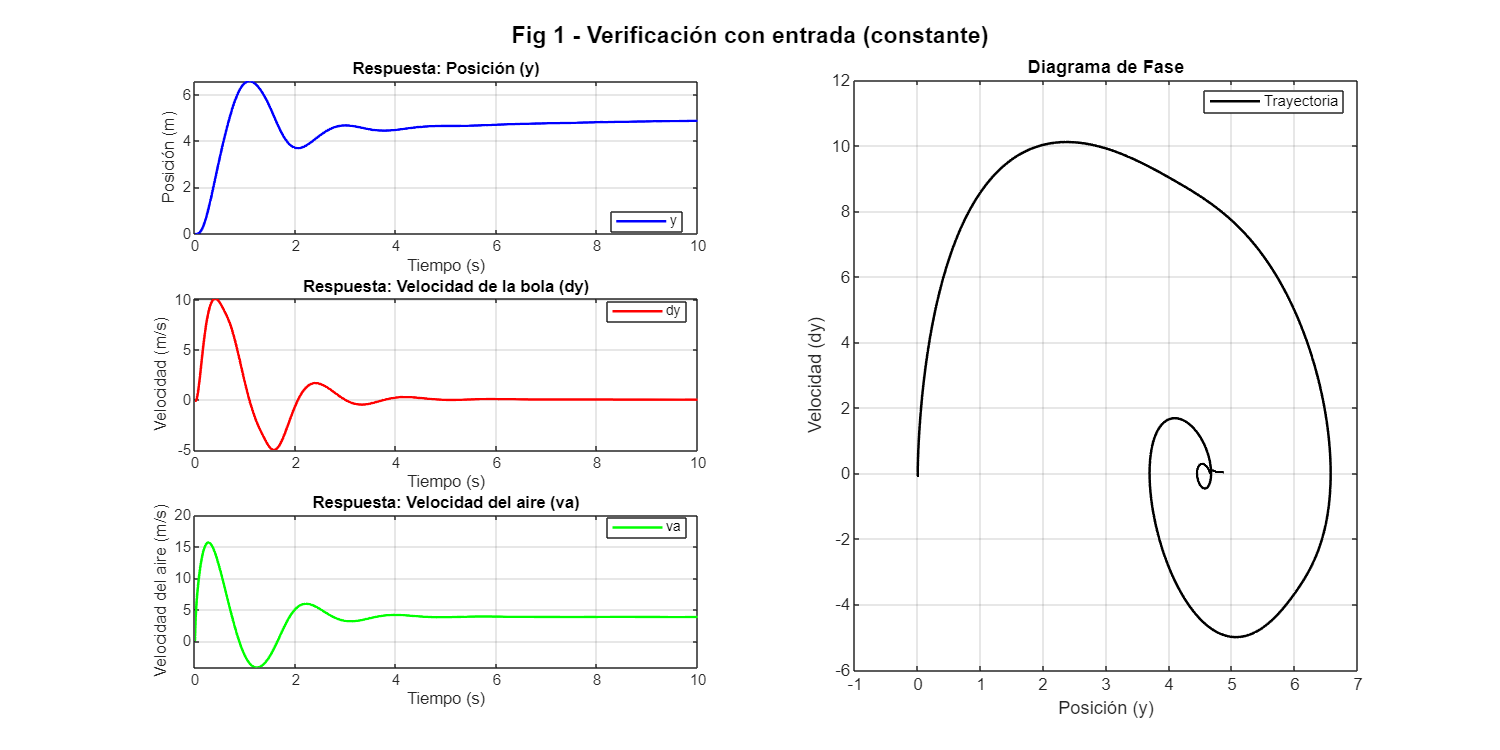

clear all;
close all;
%Tiempo máximo
T = 10;

% Create time vector (e.g., 0 to 10 seconds in 0.1 increments)
Ts = 0.1;
time = 0:Ts:T;


% Create corresponding data vector (example: sine wave)
cs = 5;
data = ones(size(time)) * cs;
% Create timeseries object
u = timeseries(data, time);
%Parámetros
g = 9.81;
m = 3.84 * 10^-3;

A = 5.7 * 10^-3;
Cd = 0.74;
rho = 1.23;

tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);

kp = 0.5;
ki = 0.1;
kd = 0.01;

%sim = ('Levitador_aire_parametrizado')
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
sim('Levitador_aire_parametrizado');
% Extraer tiempo
t_plot = y.Time;

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 1 - Verificación con entrada (constante)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

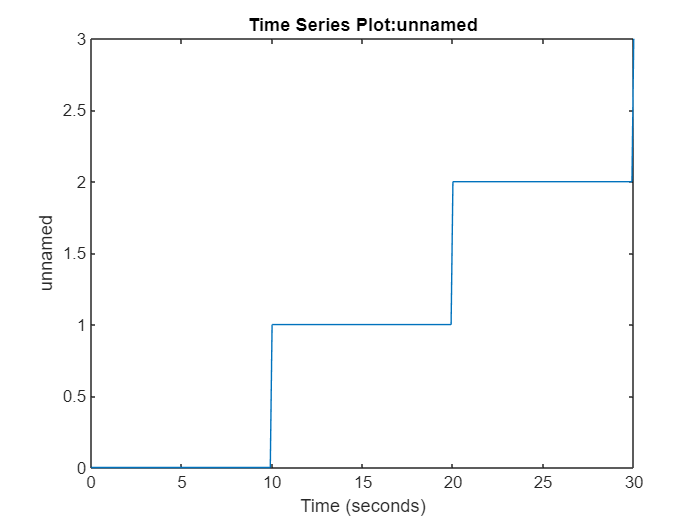

function u_ladd = ladder(T, dt, step_duration, step_size, initial_value)
    % Time vector
    time = 0:dt:T;

    % Number of steps
    num_steps = floor(T / step_duration);

    % Step values
    ladder_values = initial_value + step_size * (0:num_steps);

    % Repeat each value for the duration of a step
    samples_per_step = round(step_duration / dt);
    data = repelem(ladder_values, samples_per_step);

    % Adjust data length to match time vector
    if length(data) > length(time)
        data = data(1:length(time));
    elseif length(data) < length(time)
        data = [data, repmat(data(end), 1, length(time) - length(data))];
    end

    % Create timeseries object
    u_ladd = timeseries(data', time');
end
T = 30;
dt = 0.1;
step_duration = 10;
step_size = 1;
initial_value = 0;

u_ladd = ladder(T, dt, step_duration, step_size, initial_value);
figure;
plot(u_ladd);  % Visualize the signal

#### 3.1.2 Verificación con entrada escalón

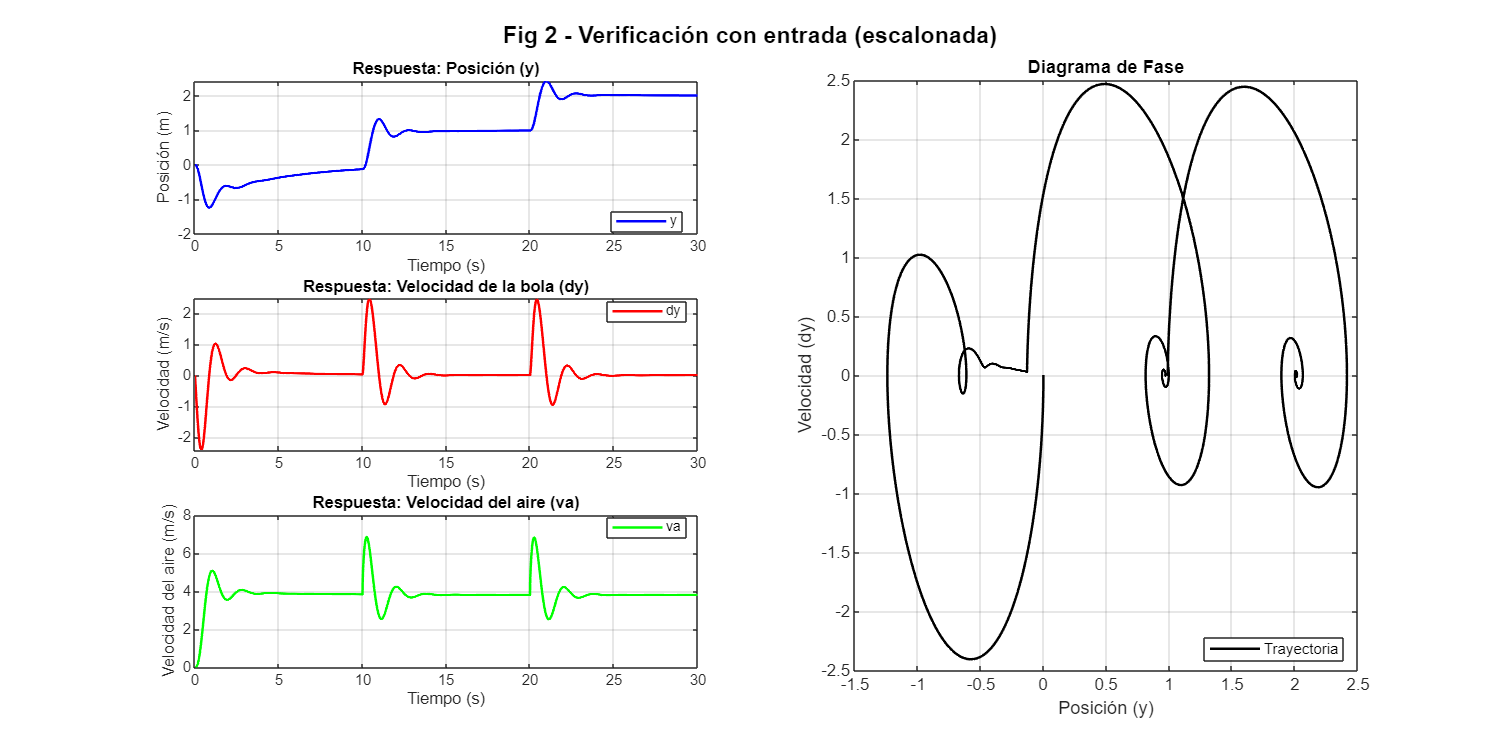

clear all;

%Tiempo máximo
T = 30;

% Create time vector (e.g., 0 to 10 seconds in 0.1 increments)
Ts = 0.1;
time = 0:Ts:T;

% Create corresponding data vector 
dt = 0.1;
step_duration = 10;
step_size = 1;
initial_value = 0;
u_l = ladder(T, dt, step_duration, step_size, initial_value);

u =  timeseries(u_l.Data, time);

%Parámetros
g = 9.81;
m = 3.84 * 10^-3;

A = 5.7 * 10^-3;
Cd = 0.74;
rho = 1.23;

tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);

kp = 0.5;
ki = 0.1;
kd = 0.01;

set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
sim('Levitador_aire_parametrizado');
t_plot = y.Time;
figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 2 - Verificación con entrada (escalonada)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

#### 3.1.3 Verificación con entrada sinusoidal

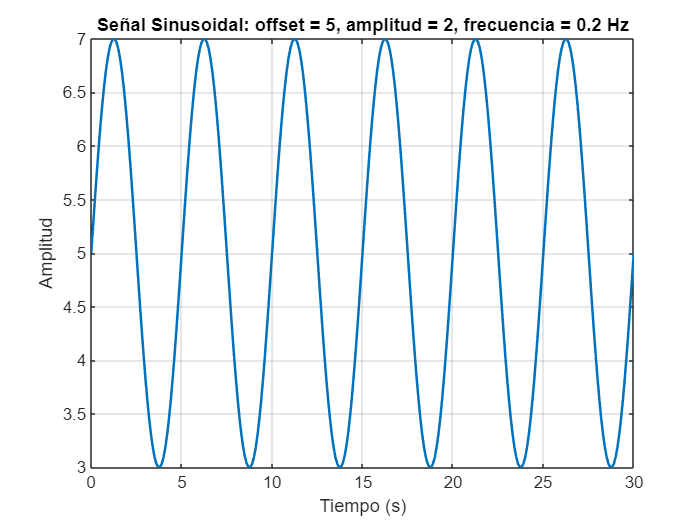

clear all;

% Tiempo máximo
T = 30;

% Crear vector de tiempo
Ts = 0.1;
time = 0:Ts:T;

% Entrada sinusoidal: Por ejemplo, una señal con offset 5 y amplitud 2
% con frecuencia 0.2 Hz (puedes ajustar estos parámetros)
offset = 5;
amplitud = 2;
frecuencia = 0.2;  % Hz
data_sin = offset + amplitud * sin(2*pi*frecuencia*time);

% Graficar la señal
figure;
plot(time, data_sin, 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal Sinusoidal: offset = 5, amplitud = 2, frecuencia = 0.2 Hz');
grid on;
% Crear objeto timeseries para la entrada sinusoidal

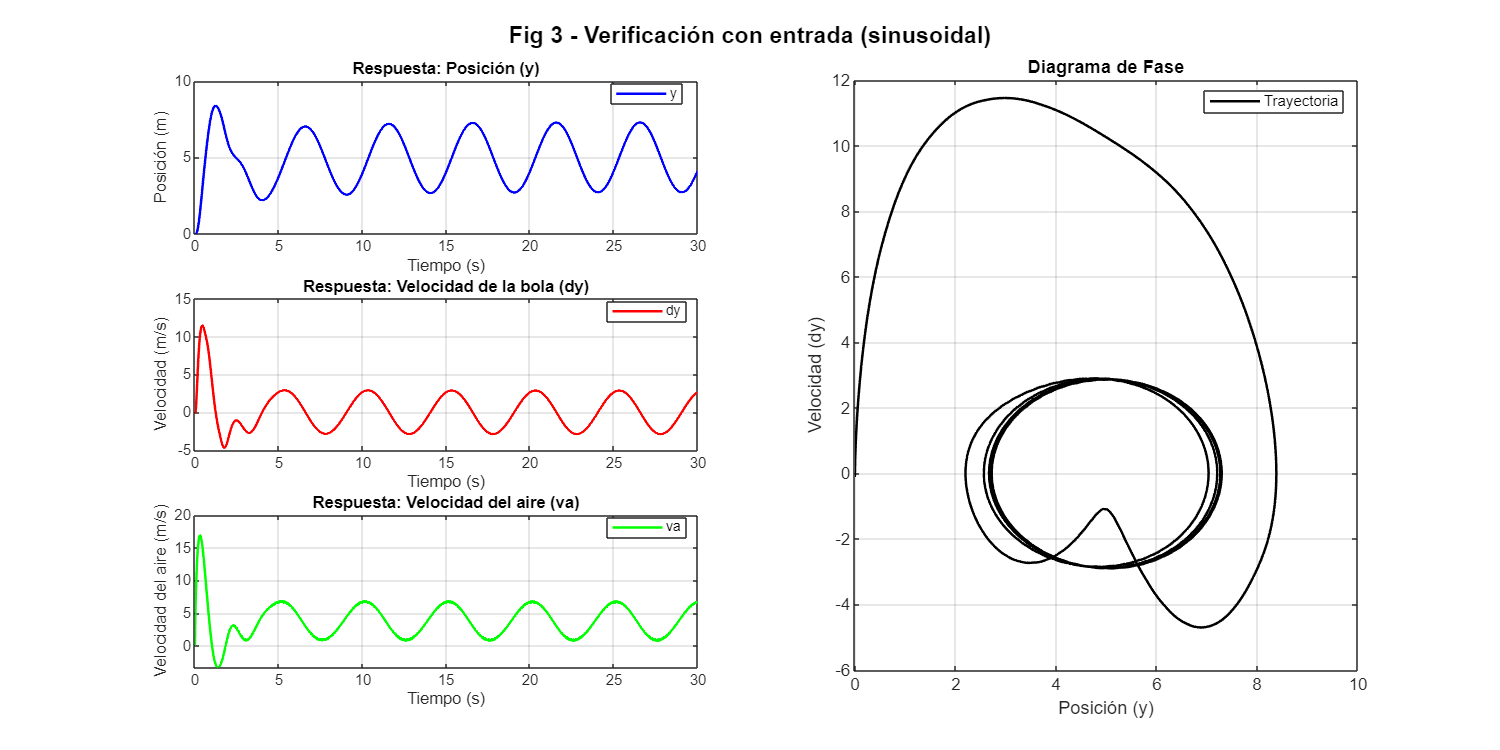

u = timeseries(data_sin, time);

% Parámetros del sistema
g = 9.81;
m = 3.84e-3;
A = 5.7e-3;
Cd = 0.74;
rho = 1.23;
tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);
kp = 0.5;
ki = 0.1;
kd = 0.01;

% Configuración de la simulación
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');

% Ejecutar simulación
sim('Levitador_aire_parametrizado');

% Acceder a las salidas (se asume que los bloques To Workspace guardan en formato Timeseries)
t_plot = y.Time;  % Usando .Time y .Data

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 3 - Verificación con entrada (sinusoidal)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

#### 3.1.4 Verificación con pulso

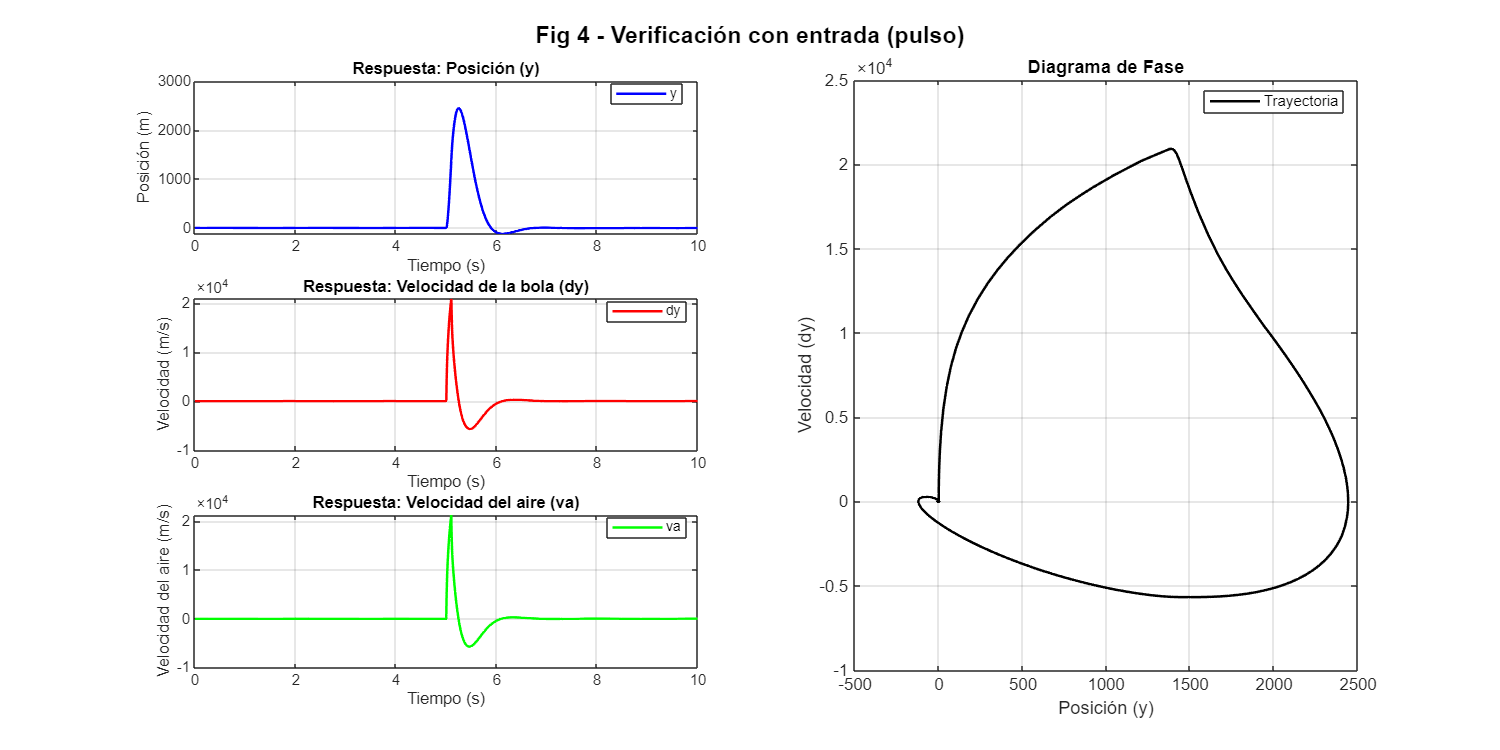

clear all;

% Tiempo máximo
T = 10;

% Crear vector de tiempo
Ts = 0.1;
time = 0:Ts:T;

% Entrada de pulso: Se crea un vector de ceros y se define un pulso en un instante específico.
data_pulse = zeros(size(time));
% Por ejemplo, se activa un pulso en t = 5 s
[~, idx] = min(abs(time-5));  % Buscar el índice más cercano a t = 5
data_pulse(idx) = 10000;  % Definir un pulso grande (puedes ajustar el valor)

% Crear objeto timeseries para la entrada de pulso
u = timeseries(data_pulse, time);

% Parámetros del sistema
g = 9.81;
m = 3.84e-3;
A = 5.7e-3;
Cd = 0.74;
rho = 1.23;
tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);
kp = 0.5;
ki = 0.1;
kd = 0.01;

% Configuración de la simulación
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');

% Ejecutar simulación
sim('Levitador_aire_parametrizado');

% Acceder a las salidas (formato Timeseries)
t_plot = y.Time;
y1 = y.Data;
y2 = dy.Data;
y3 = va.Data;

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 4 - Verificación con entrada (pulso)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

#### 3.1.5 Verificación con varios escalones

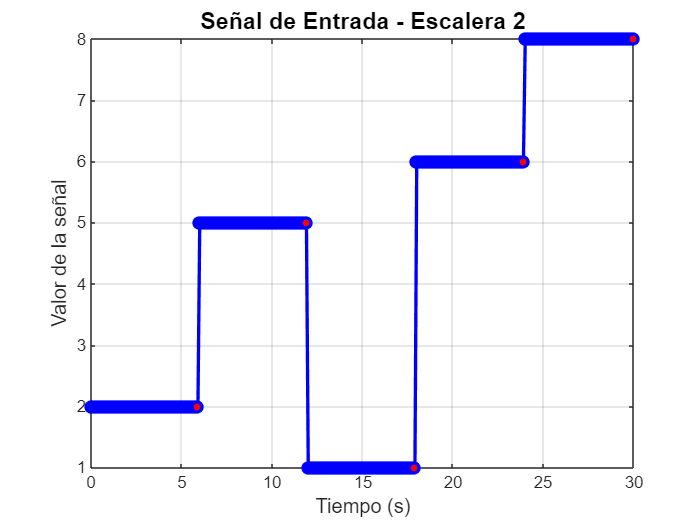

clear all;

% Tiempo máximo y paso de simulación
T = 30;
Ts = 0.1;
time = 0:Ts:T;  % Vector de tiempo de 0 a 10s con incremento de 0.1s

% Crear un vector para la señal de entrada (inicialmente en ceros)
data_ladder = zeros(size(time));

% Definir diferentes valores en distintos intervalos
% (Ajusta los intervalos y valores según la forma que desees)
idx1 = (time >= 0   & time < 6);
idx2 = (time >= 6   & time < 12);
idx3 = (time >= 12   & time < 18);
idx4 = (time >= 18   & time < 24);
idx5 = (time >= 24   & time <= 30);

data_ladder(idx1) = 2;  % Ej: valor 2 de 0 a 2s
data_ladder(idx2) = 5;  % Ej: valor 5 de 2 a 4s
data_ladder(idx3) = 1;  % Ej: valor 1 de 4 a 6s
data_ladder(idx4) = 6;  % Ej: valor 8 de 6 a 8s
data_ladder(idx5) = 8;  % Ej: valor 6 de 8 a 10s

% Crear objeto timeseries para la señal
u = timeseries(data_ladder, time);

figure;
plot(time, data_ladder, 'b-', 'LineWidth', 2, 'Marker', 'o', 'MarkerFaceColor', 'r');
xlabel('Tiempo (s)', 'FontSize', 12);
ylabel('Valor de la señal', 'FontSize', 12);
title('Señal de Entrada - Escalera 2', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
% Parámetros del sistema

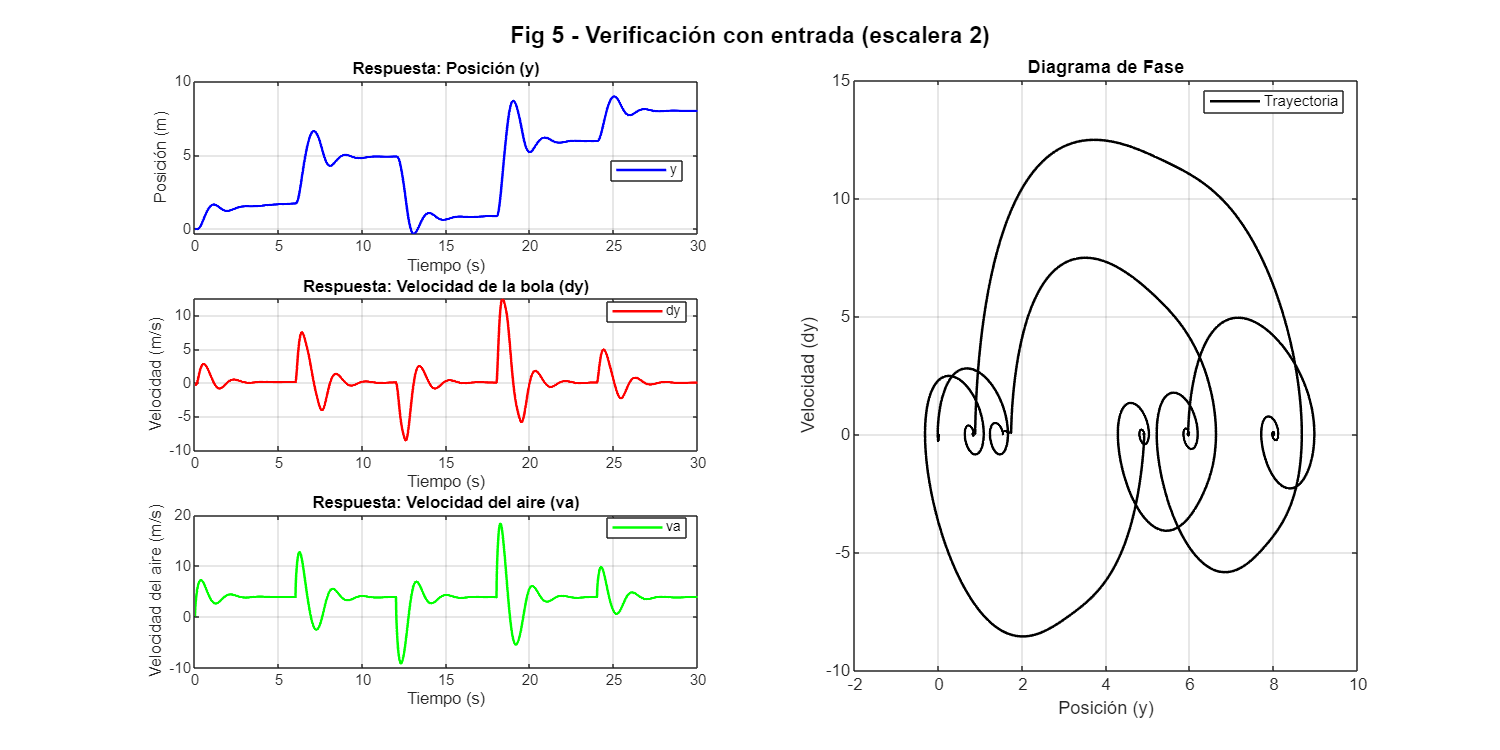

g = 9.81;
m = 3.84e-3;
A = 5.7e-3;
Cd = 0.74;
rho = 1.23;
tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);
kp = 0.5;
ki = 0.1;
kd = 0.01;

% Configuración de la simulación
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');

% Ejecutar simulación
sim('Levitador_aire_parametrizado');

% Acceder a las salidas (formato Timeseries)
t_plot = y.Time;
y1 = y.Data;
y2 = dy.Data;
y3 = va.Data;

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 5 - Verificación con entrada (escalera 2)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

### 3.2 Variación de los parámetros

#### 3.2.1 Variación de la constante de masa de la bola $m$

clear all;

% Valores a probar para la masa de la bola (m) [en kg]
%m_values = linspace(0.001, 0.03, 5);  % Por ejemplo, 5 valores desde 0.001 hasta 0.01 kg
m_values = logspace(log10(0.001), log10(0.03), 5);

% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 5 - Respuesta temporal con variación de la masa (m)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(m_values));
stabilization_values = zeros(1, length(m_values));
max_peaks = zeros(1, length(m_values));
overimpulse_values = zeros(1, length(m_values));

% Bucle para simular y graficar para cada valor de m
for i = 1:length(m_values)
    colors = lines(length(m_values));  % Genera un conjunto de colores para diferenciar las curvas
    m_val = m_values(i);  % Valor actual de la masa

    g = 9.81;
    m = m_val;
    A = 5.7e-3;
    Cd = 0.74;
    rho = 1.23;
    tao1 = 0.14;
    kf = 7.78;
    alfa = (1/2) * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 20;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Create corresponding data vector (example: sine wave)
    cs = 5;
    data = ones(size(time)) * cs;
    % Create timeseries object
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');

    % Extraer resultados de la simulación: se asume que la posición está en la primera columna
    t_sim = y.Time;
    y1 = y.Data;
    
    % Graficar la respuesta para este valor de m
    plot(t_sim, y1, 'Color', colors(i,:), 'LineWidth', 1.5)

    % Calcular valores escalares usando la función stepinfo
    info = stepinfo(y1, t_sim);
    stabilization_times(i) = info.SettlingTime;  % Tiempo de estabilización
    stabilization_values(i) = mean(y1(end-100:end));  % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(y1);  % Pico máximo
    overimpulse_values(i) = max(y1) - mean(y1(end-100:end));  % Valor de sobreimpulso
end
% Añadir leyenda para identificar cada curva
legend_entries = arrayfun(@(m_val) sprintf('m = %.4f kg', m_val), m_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off
% Crear tabla con nombres descriptivos de columnas
tabla_resultados = table(m_values', stabilization_times', stabilization_values', max_peaks', overimpulse_values', ...
    'VariableNames', {'m', 'TiempoEst', 'ValorEst', 'PicoMax', 'Sobreimpulso'});

% Mostrar tabla en la ventana de comandos
disp('Tabla de resultados para variación de m:');
disp(tabla_resultados);

Tabla de resultados para variación de m:


        m        TiempoEst    ValorEst    PicoMax    Sobreimpulso
    _________    _________    ________    _______    ____________

        0.001     6.0005        4.994     6.1079         1.1139  
    0.0023403     9.0403       4.9879     6.4197         1.4318  
    0.0054772     11.446       4.9783     6.6237         1.6454  
     0.012819     13.189       4.9658     6.1659         1.2001  
         0.03     14.156       4.9532     4.9583       0.005032  



#### 3.2.2 Variación de la constante de resistencia del aire $C_D$

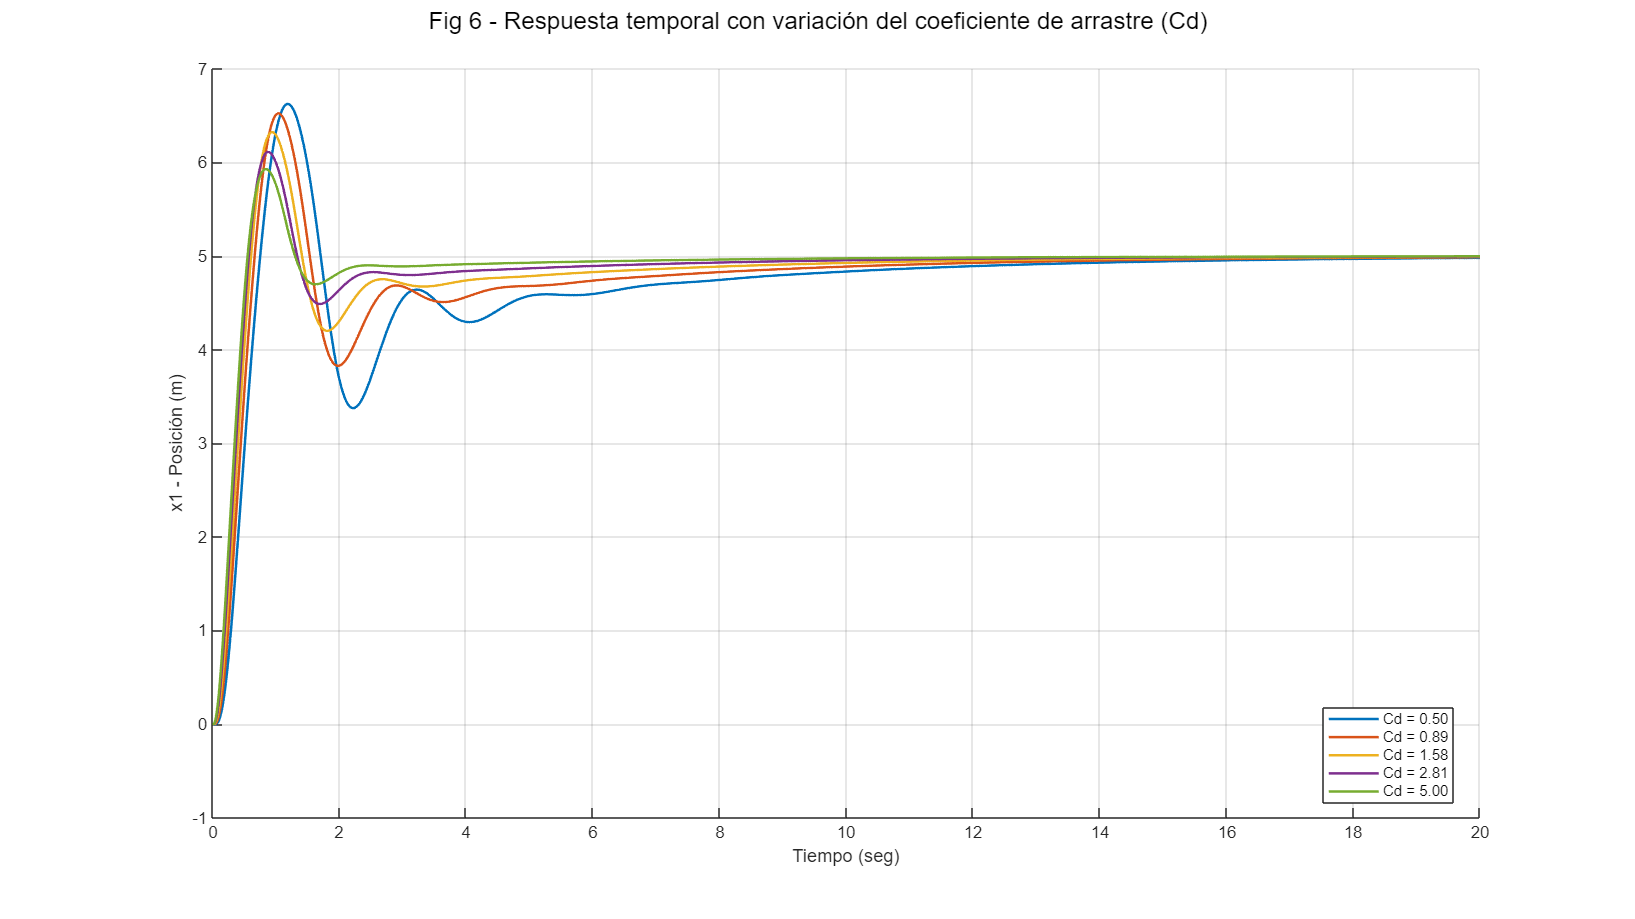

clear all;

% Valores a probar para la resistencia del aire (Cd)
%Cd_values = linspace(0.5, 5, 5);  % 5 valores entre 0.5 y 5
Cd_values = logspace(log10(0.5), log10(5), 5);
% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 6 - Respuesta temporal con variación del coeficiente de arrastre (Cd)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(Cd_values));
stabilization_values = zeros(1, length(Cd_values));
max_peaks = zeros(1, length(Cd_values));
overimpulse_values = zeros(1, length(Cd_values));

% Bucle para simular y graficar para cada valor de Cd
for i = 1:length(Cd_values)
    colors = lines(length(Cd_values));  % Genera colores para diferenciar las curvas
    cd_val = Cd_values(i);  % Valor actual de Cd

    % Parámetros constantes
    g = 9.81;
    m = 3.84e-3;    
    A = 5.7e-3;
    Cd = cd_val;           % Actualizamos Cd con el valor actual
    rho = 1.23;
    tao1 = 0.14;
    kf = 7.78;
    alfa = 0.5 * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 20;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Crear vector de entrada (constante)
    cs = 5;
    data = ones(size(time)) * cs;
    % Crear objeto timeseries para la entrada
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');

    % Extraer resultados de la simulación (se asume que la salida de posición se guarda en 'y')
    t_sim = y.Time;
    x1 = y.Data;
    
    % Graficar la respuesta para este valor de Cd
    plot(t_sim, x1, 'Color', colors(i,:), 'LineWidth', 1.5)

    % Calcular valores escalares usando la función stepinfo
    info = stepinfo(x1, t_sim);
    stabilization_times(i) = info.SettlingTime;  % Tiempo de estabilización
    stabilization_values(i) = mean(x1(end-100:end));  % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(x1);  % Pico máximo
    overimpulse_values(i) = max(x1) - mean(x1(end-100:end));  % Valor de sobreimpulso
end

% Añadir leyenda para identificar cada curva (se muestra el valor de Cd)
legend_entries = arrayfun(@(cd_val) sprintf('Cd = %.2f', cd_val), Cd_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off
% Crear tabla con nombres descriptivos de columnas

tabla_resultados = table(Cd_values', stabilization_times', stabilization_values', max_peaks', overimpulse_values', ...
    'VariableNames', {'Cd', 'TiempoEst', 'ValorEst', 'PicoMax', 'Sobreimpulso'});

% Mostrar tabla en la ventana de comandos
disp('Tabla de resultados para variación de cd:');
disp(tabla_resultados);

Tabla de resultados para variación de cd:


      Cd       TiempoEst    ValorEst    PicoMax    Sobreimpulso
    _______    _________    ________    _______    ____________

        0.5     11.539       4.9778     6.6242        1.6465   
    0.88914     9.9798       4.9849     6.5232        1.5384   
     1.5811     8.1819       4.9901     6.3226        1.3325   
     2.8117     6.0445       4.9939     6.1116        1.1177   
          5     3.3851       4.9967     5.9286       0.93189   



#### 3.2.3 **Variación de la constante de ganancia del ventilador **$K_f$

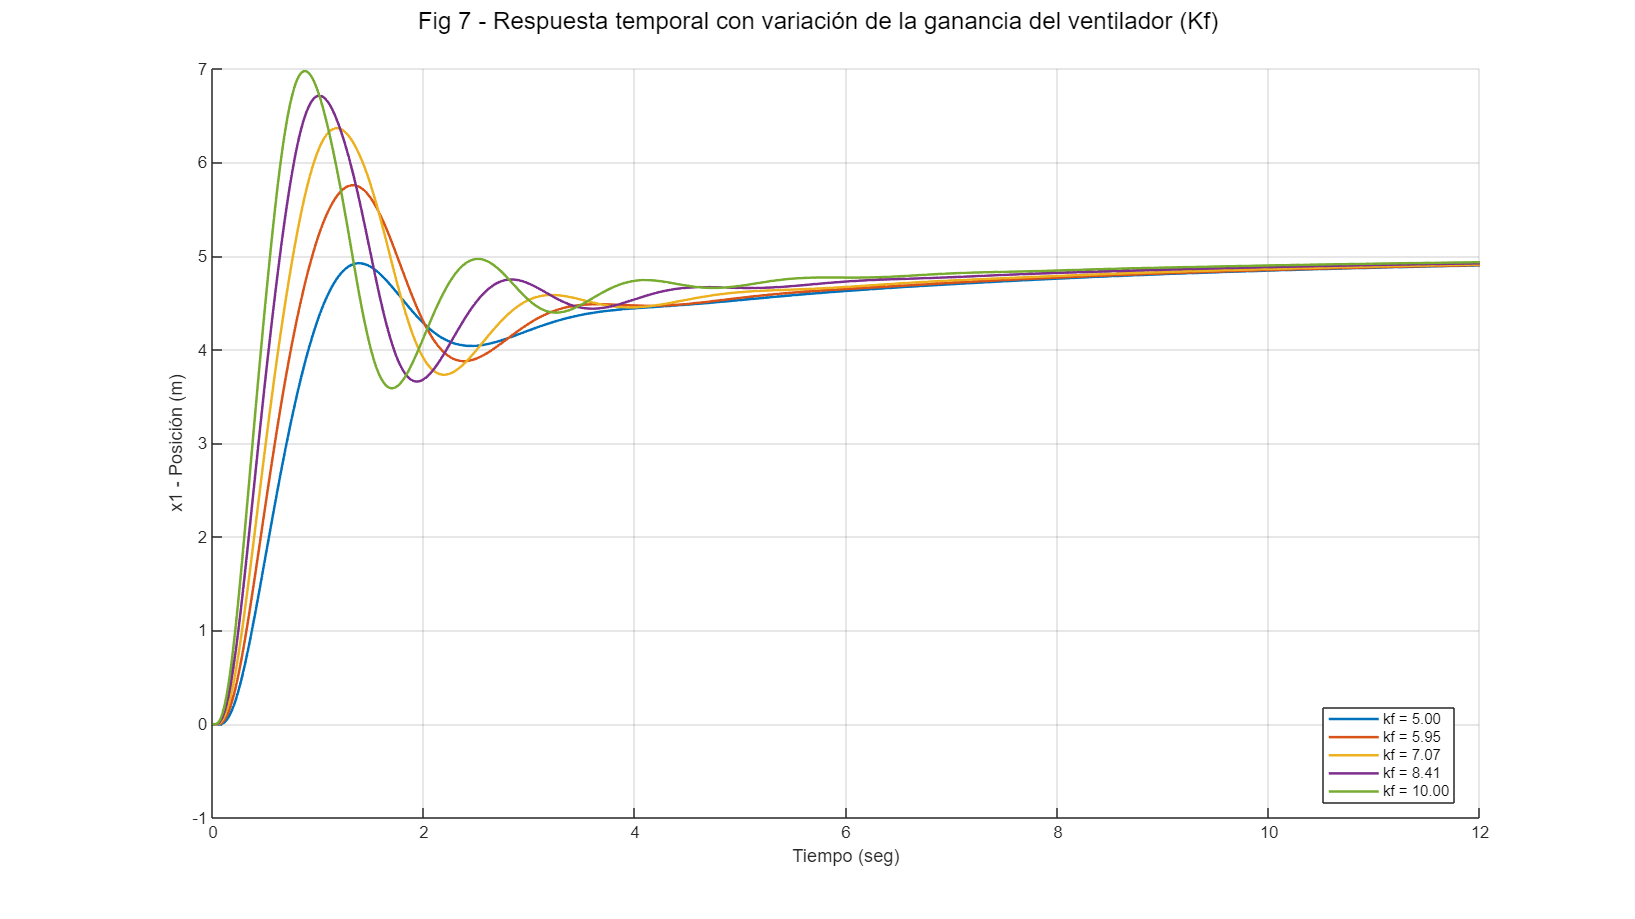

clear all;

% Valores a probar para la ganancia del ventilador (kf)
%kf_values = linspace(5, 10, 5);  % Por ejemplo, 5 valores desde 5 hasta 10
kf_values = logspace(log10(5), log10(10), 5);

% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 7 - Respuesta temporal con variación de la ganancia del ventilador (Kf)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(kf_values));
stabilization_values = zeros(1, length(kf_values));
max_peaks = zeros(1, length(kf_values));
overimpulse_values = zeros(1, length(kf_values));

% Bucle para simular y graficar para cada valor de kf
for i = 1:length(kf_values)
    colors = lines(length(kf_values));  % Genera un conjunto de colores para diferenciar las curvas
    kf_val = kf_values(i);  % Valor actual de kf

    % Parámetros constantes
    g = 9.81;
    m = 3.84e-3;        
    A = 5.7e-3;
    Cd = 0.74;       
    rho = 1.23;
    tao1 = 0.14;
    kf = kf_val;         % Actualiza la ganancia del ventilador
    alfa = 0.5 * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 12;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Crear vector de entrada (constante)
    cs = 5;
    data = cs * ones(size(time));
    % Crear objeto timeseries para la entrada
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');
    
    % Extraer resultados de la simulación: se asume que la posición está en la primera columna
    t_sim = y.Time;
    x1 = y.Data;
    
    % Graficar la respuesta para este valor de kf
    plot(t_sim, x1, 'Color', colors(i,:), 'LineWidth', 1.5)
    
    % Calcular características de la respuesta usando stepinfo
    info = stepinfo(x1, t_sim);
    stabilization_times(i) = info.SettlingTime;                % Tiempo de estabilización
    stabilization_values(i) = mean(x1(end-100:end));           % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(x1);                                    % Pico máximo
    overimpulse_values(i) = max(x1) - mean(x1(end-100:end));    % Valor de sobreimpulso
end

% Añadir leyenda para identificar cada curva (mostrando el valor de kf)
legend_entries = arrayfun(@(kf_val) sprintf('kf = %.2f', kf_val), kf_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off
% Crear tabla con nombres descriptivos de columnas

tabla_resultados = table(kf_values', stabilization_times', stabilization_values', max_peaks', overimpulse_values', ...
    'VariableNames', {'kf', 'TiempoEst', 'ValorEst', 'PicoMax', 'Sobreimpulso'});

% Mostrar tabla en la ventana de comandos
disp('Tabla de resultados para variación de kf:');
disp(tabla_resultados);

Tabla de resultados para variación de kf:


      kf      TiempoEst    ValorEst    PicoMax    Sobreimpulso
    ______    _________    ________    _______    ____________

         5     8.8934       4.8874     4.9227       0.03534   
     5.946      8.771       4.8912     5.7559       0.86474   
    7.0711      8.551       4.8989     6.3657        1.4668   
     8.409     8.1136       4.9131     6.7125        1.7994   
        10     7.6626       4.9262      6.975        2.0489   



## 4. Discusión

### 4.1 Variación de la entrada

Esta sección presenta el análisis cualitativo del comportamiento del sistema de levitación cuando se le aplican diferentes tipos de señales de entrada. El objetivo es observar cómo afecta la forma de la entrada a la estabilidad, el tiempo de respuesta y el comportamiento oscilatorio de la bola. Las observaciones se basan en las gráficas de posición, velocidad y velocidad del aire, así como en el diagrama de fase.

#### 4.1.1 Entrada constante

Cuando se aplica una señal constante (por ejemplo, $u=5$), la bola tiende a estabilizarse en una posición fija. Se observa una respuesta típica de un sistema de segundo orden con amortiguamiento, donde la bola primero acelera, luego oscila levemente y finalmente converge a una altura de equilibrio. El sistema disipa energía a través de la fricción del aire, lo que permite que la velocidad de la bola disminuya progresivamente hasta alcanzar un valor cercano a cero. El diagrama de fase muestra una espiral que converge hacia un punto, lo cual es consistente con un sistema **estable y amortiguado**.

#### 4.1.2 Entrada tipo escalera

La segunda prueba utilizó una señal escalonada creciente, en la que el valor de entrada aumenta gradualmente cada cierto intervalo de tiempo. En este caso, el sistema responde a cada incremento de la señal ajustando su altura progresivamente. Se observan oscilaciones más marcadas cuando sube el paso, las cuales disminuyen a medida que la bola alcanza una nueva posición de equilibrio, esta entrada permite evaluar la capacidad del sistema para adaptarse a cambios progresivos en la señal de control.

#### 4.1.3 Entrada sinusoidal

La tercera señal corresponde a una onda sinusoidal con un valor medio de 5 y una amplitud de 2, oscilando con una frecuencia de 0.2 Hz. Esta entrada introduce una excitación periódica, obligando al sistema a variar su altura de forma continua. La bola intenta seguir el patrón de la señal, aunque con un retardo de fase debido a la inercia del sistema. La velocidad del aire también se ajusta de manera periódica, y la velocidad de la bola oscila con cierta amplitud dependiendo del amortiguamiento. El diagrama de fase no llega hasta un equilibrio en 0, pero si se mantiene oscilando entre valores de 2.5 y -2.5, lo cual indica que se mantiene estable en ese intervalo.

#### 4.1.4 Entrada tipo pulso

En la cuarta simulación se aplicó una señal tipo pulso: una entrada extremadamente grande (por ejemplo, $u=10000$) aplicada únicamente durante un instante breve. El resultado es una respuesta transitoria explosiva: la bola es impulsada con una aceleración intensa hacia arriba y luego comienza a descender en caída libre, ya que el ventilador no sigue suministrando energía. La velocidad inicial es muy alta y decrece progresivamente debido a la gravedad y a la resistencia del aire. El sistema no alcanza un punto de equilibrio sino que describe una trayectoria balística. El diagrama de fase muestra una curva abierta y ascendente seguida de un retorno descendente, típica de un sistema sin retroalimentación activa. Este tipo de entrada es ideal para estudiar la inercia y la disipación del sistema.

#### 4.1.5 Entrada con múltiples escalones manuales

Por último, se utilizó una señal con varios niveles definidos manualmente, donde la entrada cambia de valor en intervalos regulares (por ejemplo, $u=2,5,1,6,8$). Este tipo de señal permite evaluar cómo reacciona el sistema ante cambios abruptos e impredecibles. Se observa que tras cada salto de la señal, la bola responde con un transitorio que incluye sobreimpulso y oscilaciones, antes de ajustarse a la nueva posición de equilibrio. Los efectos son acumulativos: las oscilaciones tienden a amplificarse si los cambios en la entrada son muy bruscos o si no hay suficiente amortiguamiento. Este experimento muestra claramente el efecto combinado de la dinámica del sistema y la no linealidad de la fricción.

### 4.2 Variación de parámetros

#### 4.2.1 Variación de la masa ($m$)

En general, se puede observar que para los rangos de masa seleccionados, mientras mayor es la masa, más tiempo demora el sistema en estabilizarse. Al observar los picos de altura antes de alcanzar la estabilización se evidencia un comportamiento interesante. Inicialmente, el aumento de masa provoca que la bola tenga un pico más grande (hasta aproximadamente $0.0055\,\text{kg}$), pero al seguir incrementando la masa, los picos de altura comienzan a disminuir. Esto indica que existe un punto donde la inercia generada por la masa supera el impulso inicial, haciendo que el sistema responda más lentamente y con menor oscilación.

#### 4.2.2 Variación del coeficiente de arrastre ($C_d$)

Para los valores seleccionados del coeficiente de resistencia aerodinámica $C_d$, se observa que a mayor resistencia, la bola oscila menos y se estabiliza más rápidamente. Este comportamiento puede explicarse por el hecho de que una mayor resistencia genera una respuesta más inmediata frente a los cambios en la velocidad del aire, funcionando como un efecto amortiguador natural. Por el contrario, cuando el coeficiente de resistencia es bajo, se requiere mayor flujo de aire para generar la misma aceleración, lo cual provoca que el controlador reaccione de forma exagerada, causando mayores oscilaciones y retardando la estabilización. Además, se observa que a menor $C_d$, los picos de altura son notablemente más altos.

\subsubsection{Variación de $k_f$ (Ganancia del ventilador)}

Al variar la ganancia del ventilador $k_f$, se evidencian varias características relevantes. Una de ellas es que, para los valores seleccionados, el tiempo de estabilización se mantiene prácticamente constante. No obstante, se observa que a medida que $k_f$ aumenta, el sistema presenta más oscilaciones en su respuesta. También se nota que el pico de altura alcanzado por la bola incrementa con valores más altos de $k_f$. Esto se debe a que un ventilador con mayor ganancia produce un empuje más fuerte ante la misma señal de entrada, generando una mayor aceleración inicial en la bola, lo que resulta en picos más altos y un comportamiento más oscilatorio antes de estabilizarse.

## **Referencias**